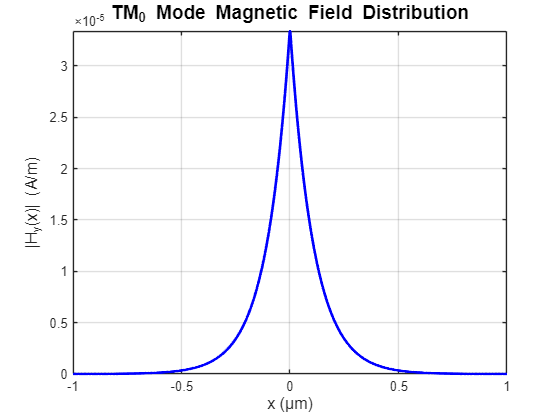

clear; clc; close all;

% Given parameters
lambda = 1.55e-6;   % um
a = 0.225e-6;       % um
n1 = 2.94;  
ns = 1.46;  
no = 1.00;
P = 1;              % W/m
k0 = 2*pi/lambda;   % Free space wavenumber

% Constants
mu0 = 4e7 * pi;
omega = 2*pi*3e8/lambda;  % angular frequency
epsilon0 = 8.854e-12;     % F/m

% Linespace range
x = linspace(-1e-6, 1e-6, 1000);  % um

v = k0*a*sqrt(n1^2 - ns^2);

% Define equation to solve for b
eq = @(b) v*sqrt(1-b) - atan(sqrt(b./(1-b)));
b = fzero(eq, 0.5);

ne = sqrt(ns^2 + b*(n1^2 - ns^2));
beta = k0*ne;

kappa = k0*sqrt(n1^2 - ne^2);
gamma = k0*sqrt(ne^2 - ns^2);

% Integral of |Hy|^2 for TM0 mode
integral_Hy2 = 2*a + 1/gamma * (1 + (kappa*sin(2*kappa*a))/(2*kappa*a));

% From power normalization: P = (beta*omega*epsilon0/2) * integral
A_squared = (2*P) / (beta*omega*epsilon0*integral_Hy2);
A = sqrt(A_squared);

% Calculate |Hy(x)| for TM0 mode
Hy = zeros(size(x));
for i = 1:length(x)
    if abs(x) <= a
        Hy(i) = A*cos(kappa*x(i));
    else
        Hy(i) = A*cos(kappa*a) * exp(-gamma*(abs(x(i))-a));
    end
end

% Plot
figure;
plot(x*1e6, abs(Hy), 'b-', 'LineWidth', 2);
xlabel('x (µm)', 'FontSize', 12);
ylabel('|H_y(x)| (A/m)', 'FontSize', 12);
title('TM_0 Mode Magnetic Field Distribution', 'FontSize', 14);
grid on;
ylim([0, max(abs(Hy))]);
xlim([-1, 1]);


% Display parameters
fprintf('v-parameter = %.6f\n', v);

v-parameter = 2.327490


fprintf('b-parameter = %.6f\n', b);

b-parameter = 0.782461


fprintf('Parameter β = %.6e rad/m\n', beta);

Parameter β = 1.089750e+07 rad/m


fprintf('Parameter A = %.6e A/m\n', A);

Parameter A = 9.222658e-06 A/m


fprintf('Effective index n_e = %.6f\n', ne);

Effective index n_e = 2.688305
